%exponential
syms lambda t;
pdf = lambda*exp(-lambda*t)

$$pdf = \lambda \,{\mathrm{e}}^{-\lambda \,t}$$

cdf = int(pdf,t)+1 %+C is kinda cheeted

$$cdf = 1-{\mathrm{e}}^{-\lambda \,t}$$

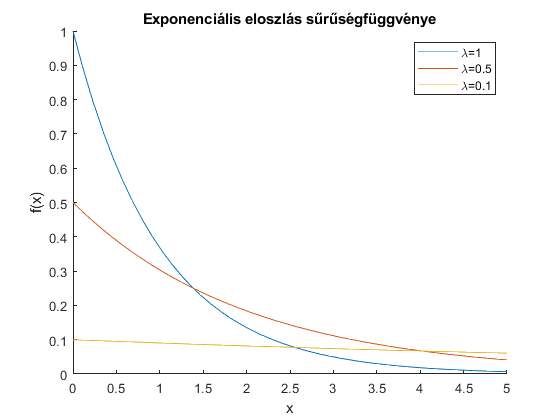

lambda_examples = [1,0.5,0.1];
legends = repmat("default",numel(lambda_examples),1);

figure;
%title('pdf of exponential distribution');
title('Exponenciális eloszlás sűrűségfüggvénye');
xlabel('x');
ylabel('f(x)');
hold on;
for i = 1:numel(lambda_examples)
    lambda = lambda_examples(i);
    fplot(subs(pdf),[0,5]);
    legends(i) = "\lambda=" + lambda;
end
hold off;
legend(legends);

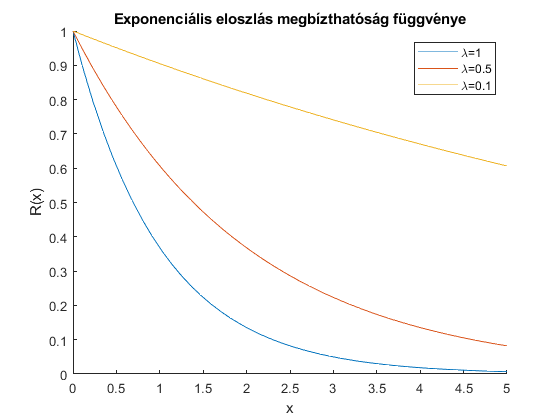

figure;
%title('1-cdf = R(x) of exponential distribution');
title('Exponenciális eloszlás megbízthatósági függvénye');
xlabel('x');
ylabel('R(x)');
hold on;
for i = 1:numel(lambda_examples)
    lambda = lambda_examples(i);
    fplot(subs(1-cdf),[0,5]);
    legends(i) = "\lambda=" + lambda;
end
hold off;
legend(legends,"Location","northeast");

%weibull
syms beta eta t;
pdf = (beta/eta)*power(t/eta,beta-1)*exp(-power(t/eta,beta))

$$pdf = \frac{\beta \,{\mathrm{e}}^{-{\left(\frac{t}{\eta }\right)}^{\beta }}\,{\left(\frac{t}{\eta }\right)}^{\beta -1}}{\eta }$$

cdf = int(pdf,t)+1 %+C is kinda cheeted

$$cdf = \sinh\left({\left(\frac{t}{\eta }\right)}^{\beta }\right)-\cosh\left({\left(\frac{t}{\eta }\right)}^{\beta }\right)+1$$

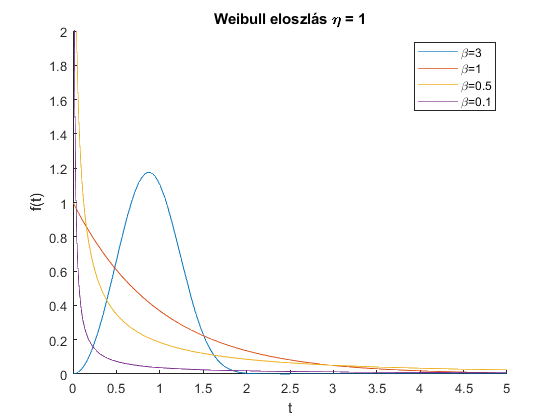

beta_examples = [3,1,0.5,0.1];
eta_examples = [3,1,0.5];
eta = 1;
legends = repmat("default",numel(beta_examples),1);

figure;
%title(['pdf of 2 param Weibull distribution \eta = ' int2str(eta)]);
title(['Weibull eloszlás \eta = ' int2str(eta)]);
xlabel('t');
ylabel('f(t)');
hold on;
for i = 1:numel(beta_examples)
    beta = beta_examples(i);
    fplot(subs(pdf),[0,5]);
    legends(i) = "\beta=" + beta;
end
hold off;
ylim([0,2]);
legend(legends);

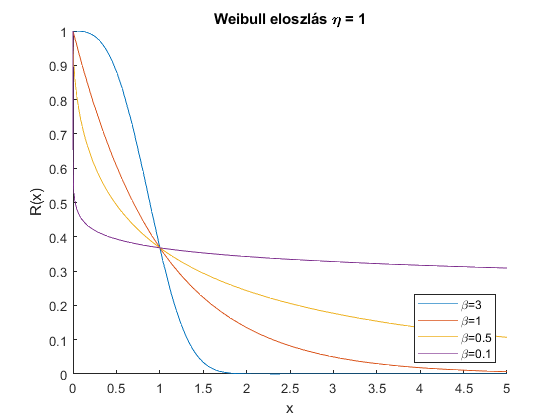

figure;
%title(['cdf of 2 param Weibull distribution \eta = ' int2str(eta)]);
title(['Weibull eloszlás \eta = ' int2str(eta)]);
xlabel('x');
ylabel("R(x)");
hold on;
for i = 1:numel(beta_examples)
    beta = beta_examples(i);
    fplot(subs(1-cdf),[0,5]);
    legends(i) = "\beta=" + beta;
end
hold off;
legend(legends,"Location","southeast");

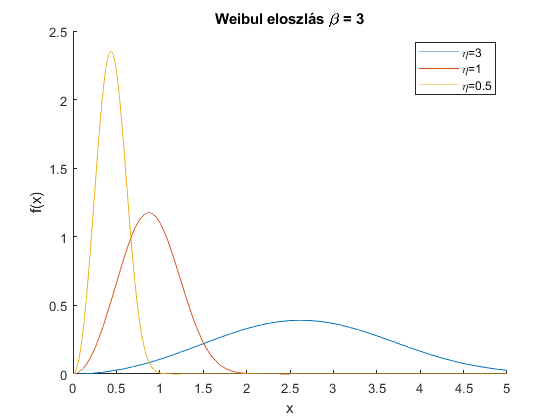

figure;
legends = repmat("default",numel(eta_examples),1);
%title(['pdf of 2 param Weibull distribution \beta = ' int2str(3)]);
title(['Weibul eloszlás \beta = ' int2str(3)]);
ylabel("f(x)");
xlabel('x');
beta = 3;
hold on;
for i = 1:numel(eta_examples)
    eta = eta_examples(i);
    fplot(subs(pdf),[0,5]);
    legends(i) = "\eta=" + eta;
end
hold off;
legend(legends);

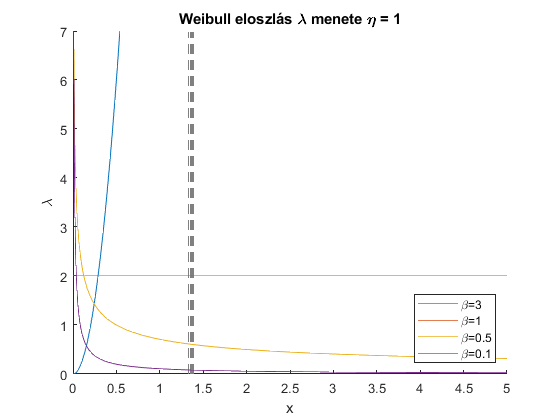

figure;
%title(['cdf of 2 param Weibull distribution \eta = ' int2str(eta)]);
title(['Weibull eloszlás \lambda menete \eta = ' int2str(eta)]);
xlabel('x');
ylabel('\lambda');
hold on; 
for i = 1:numel(beta_examples)
    beta = beta_examples(i);
    fplot(subs(pdf/(1-cdf)),[0,5]);
    legends(i) = "\beta=" + beta;
end
ylim([0,7]);
hold off;
legend(legends,"Location","southeast");